# Analysis of Wind Turbine data -- Accleration

#### Dataset: D2C2SG1 -- Accleration labeled data 

**Description:** This dataset is from acclerometers in the tower area of the offshore Wind turbine.

#### Author: Vishu Sharma

#### Last Modified: 29.02.2023

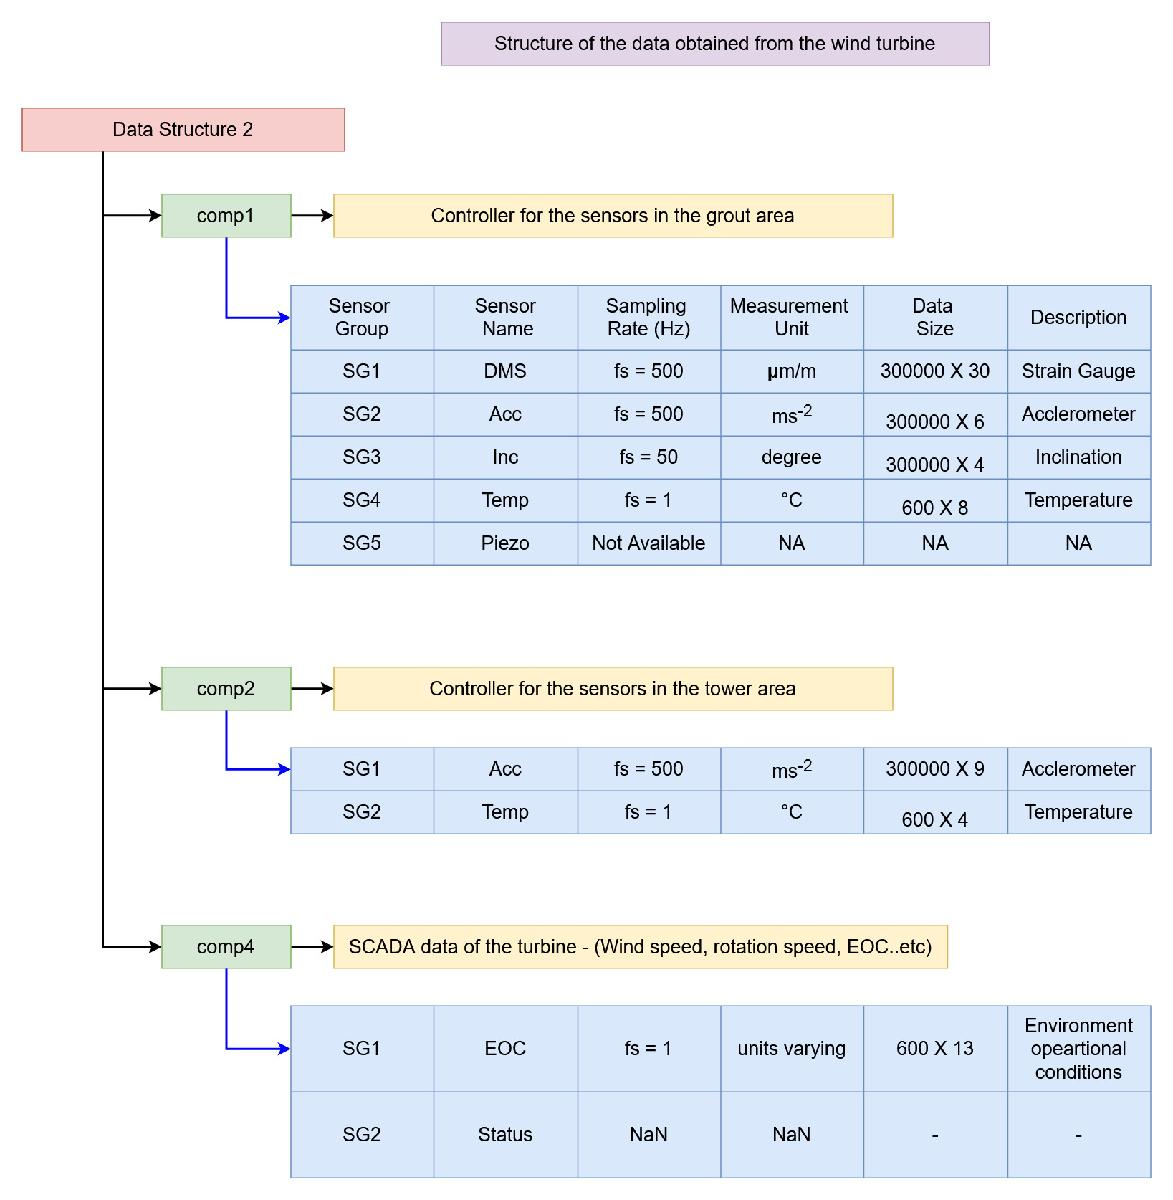

clear all, clc

% Loading data sets from CSV files

A = readmatrix("D:\University of Siegen\uos\research Project\Codes\Data\WT_labeled_data\D2C2SG1_Acc_Labeled.csv");

% Labeled variables for accleration signal 2

Acc3_z     = A(:,7);
Acc3_y     = A(:,8);
Acc3_x     = A(:,9);

% Constructing time vector 

Fs = 500;            % Sampling frequency
T = 1/Fs;            % Sampling period
L = 300000;          % length of signal
t = (0: L-1)*T;      % Time vector

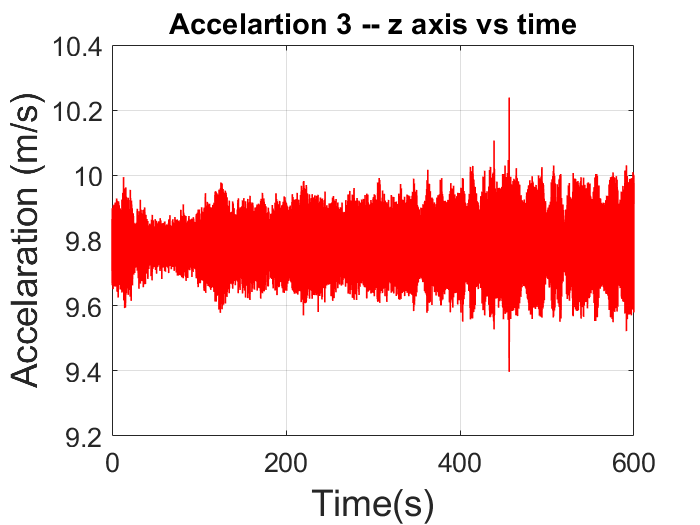

% Time Domain preliminary analysis -- Accelarations 3 z -axis

plot(t, Acc3_z, 'r','LineWidth',1)
title('Accelartion 3 -- z axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc3_z)

ans = 9.7849

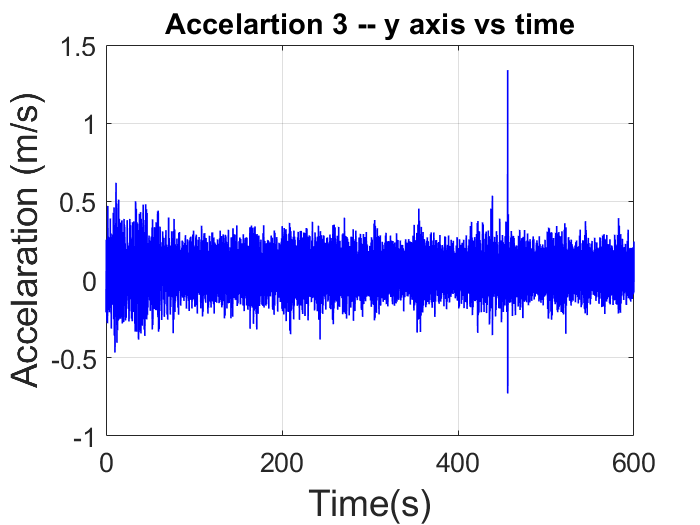

% Time Domain preliminary analysis -- Accelarations 3 y -axis

plot(t, Acc3_y, 'b','LineWidth',1)
title('Accelartion 3 -- y axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc3_y)

ans = 0.0549

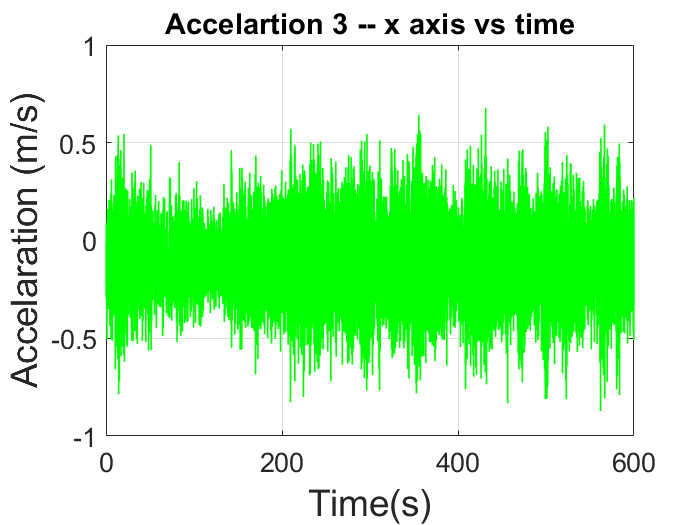

% Time Domain preliminary analysis -- Accelarations 2 x -axis

plot(t, Acc3_x, 'g','LineWidth',1)
title('Accelartion 3 -- x axis vs time','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Accelaration (m/s)', 'FontSize', 22)

grid on

mean(Acc3_x)

ans = -0.1067

% Zero mean values for accleration

ZM_Acc3_z = Acc3_z - mean(Acc3_z);
ZM_Acc3_y = Acc3_y - mean(Acc3_y);
ZM_Acc3_x = Acc3_x - mean(Acc3_x);

#### Fourier Spectral Analysis of accleration 1 signals

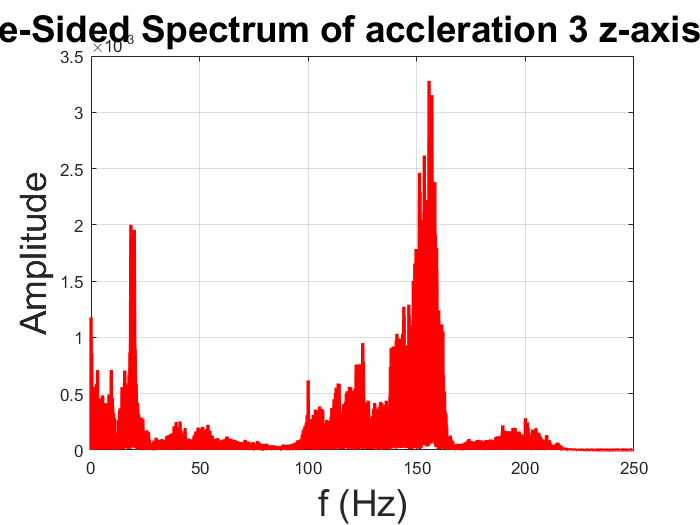

% Fourier Spectrum for z axis accleration - 3


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc3_z);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum of accleration 3 z-axis signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

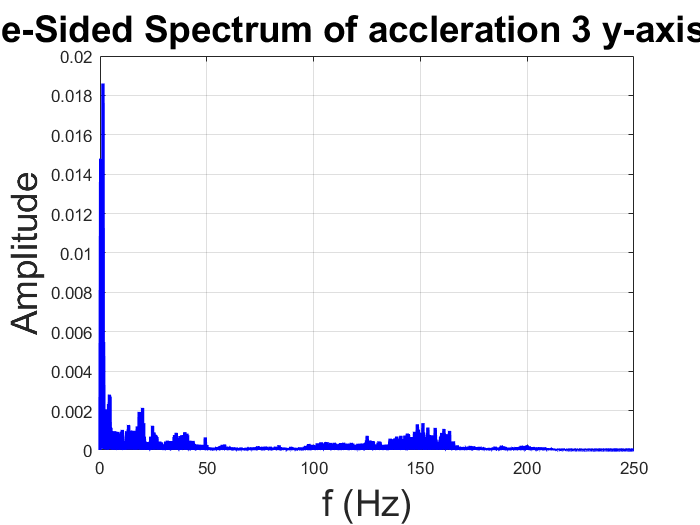

% Fourier Spectrum for y axis accleration - 3


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc3_y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'b','LineWidth',2) 

title('Single-Sided Spectrum of accleration 3 y-axis signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

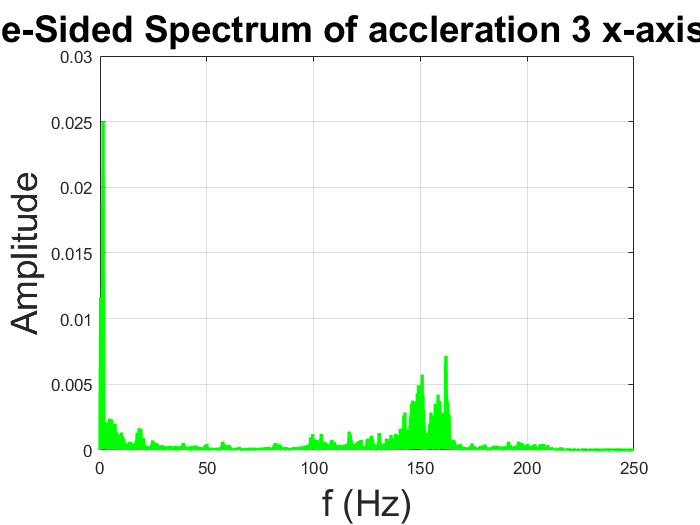

% Fourier Spectrum for x axis accleration - 3


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Acc3_x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'g','LineWidth',2) 

title('Single-Sided Spectrum of accleration 3 x-axis signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

#### Spectrograms for accleration 3 signals

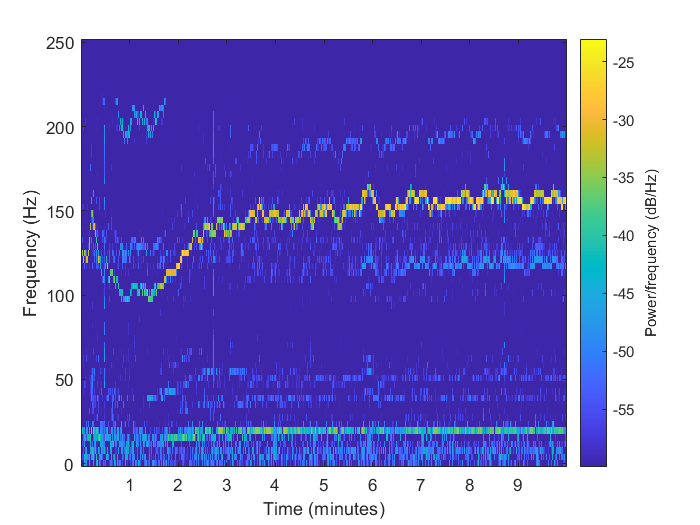

% Spectrogram for z-axis signal

s = spectrogram(ZM_Acc3_z);
spectrogram(ZM_Acc3_z, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

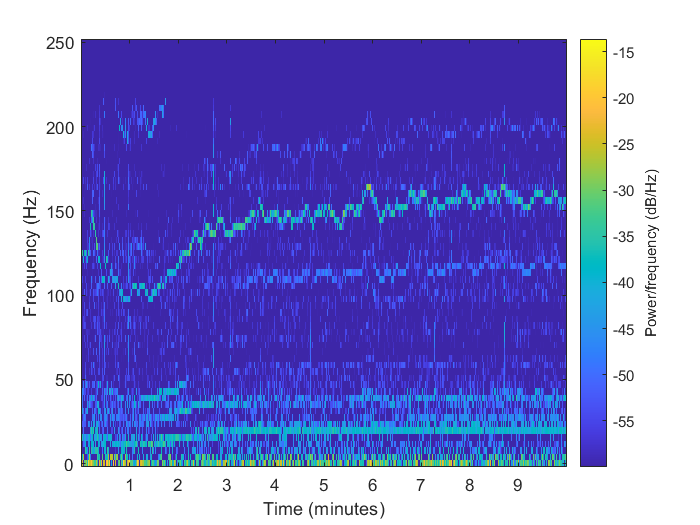

% Spectrogram for y-axis signal

s = spectrogram(ZM_Acc3_y);
spectrogram(ZM_Acc3_y, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

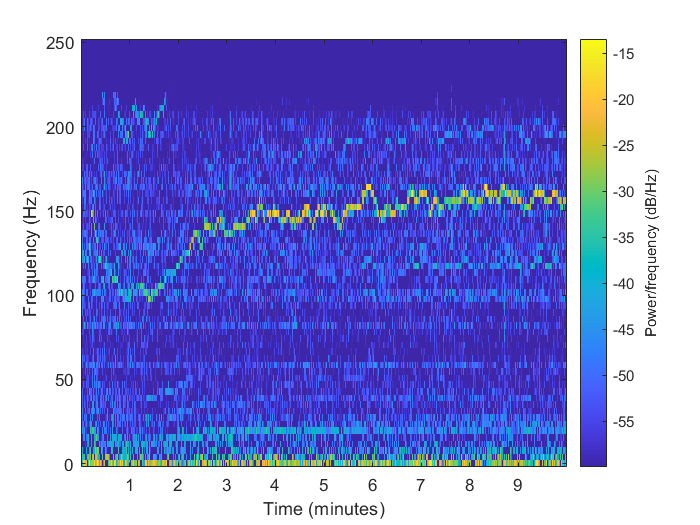

% Spectrogram for x-axis signal

s = spectrogram(ZM_Acc3_x);
spectrogram(ZM_Acc3_x, window(@hanning,128), 64, 128, Fs,'yaxis', 'reassign','MinThreshold', -60)

#### Hilbert Spectral Analysis for Accleration signal